
$$f\left(x\right)=\left\lbrace \begin{array}{cc}
\frac{x^2 }{4} & 0\le x<4\\
4 & 4\le x<6\\
0 & 6\le x<8
\end{array}\right.$$
 
$$f\left(x+8\right)=f\left(x\right)$$


syms t;
f = (t^2/4).*(heaviside(t-0)-heaviside(t-4))+4.*(heaviside(t-4)-heaviside(t-6))

$$f = 4\,\mathrm{heaviside}\left(t-4\right)-4\,\mathrm{heaviside}\left(t-6\right)-\frac{t^{2}\,\left(\mathrm{heaviside}\left(t-4\right)-\mathrm{heaviside}\left(t\right)\right)}{4}$$

fourier(f)

$$ans = \begin{array}{l} -\frac{\sin\left(4\,w\right)+\cos\left(4\,w\right)\,\mathrm{i}}{2\,w^{3}}+4\,{\mathrm{e}}^{-4\,w\,\mathrm{i}}\,\sigma_{1}-4\,{\mathrm{e}}^{-6\,w\,\mathrm{i}}\,\sigma_{1}+\frac{\mathrm{i}}{2\,w^{3}}+\frac{4\,\cos\left(4\,w\right)-4\,\sin\left(4\,w\right)\,\mathrm{i}}{2\,w^{2}}+\frac{16\,\sin\left(4\,w\right)+16\,\cos\left(4\,w\right)\,\mathrm{i}}{4\,w}\\ \mathrm{where}\\ \sigma_{1}=\pi \,\delta (w)-\frac{\mathrm{i}}{w} \end{array}$$

laplace(f)

$$ans = \frac{1}{2\,s^{3}}-\frac{4\,{\mathrm{e}}^{-6\,s}}{s}-\frac{{\mathrm{e}}^{-4\,s}}{2\,s^{3}}-\frac{2\,{\mathrm{e}}^{-4\,s}}{s^{2}}$$

find fourier of $f\left(t\right)=\left\lbrace \begin{array}{cc}
1-|t| & -1\le t<1\\
0 & \mathrm{otherwise}
\end{array}\right.$

syms t;
f = (1-abs(t)).*(heaviside(t-(-1)) - heaviside(t-1));
fourier(f)

$$ans = \frac{2}{w^{2}}+\frac{{\mathrm{e}}^{w\,\mathrm{i}}\,\mathrm{i}}{w}-\frac{{\mathrm{e}}^{-w\,\mathrm{i}}}{w^{2}}-\frac{{\mathrm{e}}^{w\,\mathrm{i}}}{w^{2}}+\frac{\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}-\frac{-\sin\left(w\right)+\cos\left(w\right)\,\mathrm{i}}{w}-\frac{{\mathrm{e}}^{-w\,\mathrm{i}}\,\mathrm{i}}{w}$$


$$f\left(t\right)=\left\lbrace \begin{array}{cc}
t\ldotp e^t  & t>0\\
0 & \mathrm{otherwise}
\end{array}\right.$$


syms t;
f = (t*exp(t)).*(heaviside(t-0))

$$f = t\,{\mathrm{e}}^{t}\,\mathrm{heaviside}\left(t\right)$$

fourier(f)

$$ans = \frac{1}{{\left(-1+w\,\mathrm{i}\right)}^{2}}+\mathrm{fourier}\left(t\,{\mathrm{e}}^{t},t,w\right)$$


$$F=\frac{x}{z}i-\frac{y}{z}j+\frac{z}{4}k$$



$$-2\le x\le 2;-2\le y\le 2;-2\le z\le 2$$


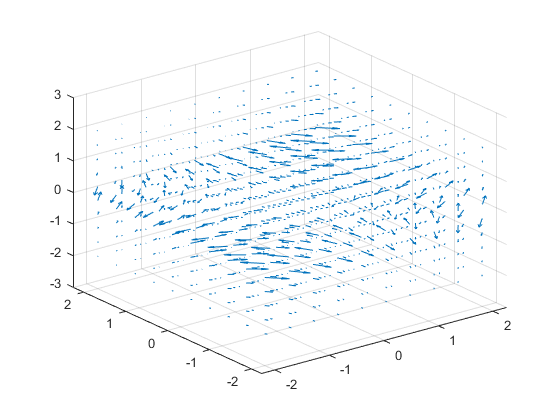

a = linspace(-2, 2, 10);
[x, y, z] = meshgrid(a, a, a);
u = x./z;
v = -y./z;
w = z/4;
quiver3(x, y, z, u, v, w);